close all; clear all; clc;

syms a bx by

f = [ 2*a*by 0 a^2;
      3*a^2*bx^2 2*a^3*bx 0]

$$f = \left(\begin{array}{ccc} 2\,a\,\mathrm{by} & 0 & a^{2}\\ 3\,a^{2}\,{\mathrm{bx}}^{2} & 2\,a^{3}\,\mathrm{bx} & 0 \end{array}\right)$$


f = [a^2 * by; a^3 * bx^2]

$$f = \left(\begin{array}{c} a^{2}\,\mathrm{by}\\ a^{3}\,{\mathrm{bx}}^{2} \end{array}\right)$$

jacobian(f)

$$ans = \left(\begin{array}{ccc} 2\,a\,\mathrm{by} & 0 & a^{2}\\ 3\,a^{2}\,{\mathrm{bx}}^{2} & 2\,a^{3}\,\mathrm{bx} & 0 \end{array}\right)$$


lam_x = [ 5 0 0;
        0 4 1;
        0 2 5]

lam_x =      5     0     0
     0     4     1
     0     2     5



lamba_y = jacobian(f) * lam_x * jacobian(f)'

$$lamba\_y = \left(\begin{array}{cc} 5\,a^{2}\,{\left(\bar{a}\right)}^{2}+20\,\mathrm{by}\,\bar{\mathrm{by}}\,a\,\bar{a} & 4\,a^{2}\,{\left(\bar{a}\right)}^{3}\,\bar{\mathrm{bx}}+30\,\mathrm{by}\,a\,{\left(\bar{a}\right)}^{2}\,{\left(\bar{\mathrm{bx}}\right)}^{2}\\ 2\,a^{3}\,\mathrm{bx}\,{\left(\bar{a}\right)}^{2}+30\,\bar{\mathrm{by}}\,a^{2}\,{\mathrm{bx}}^{2}\,\bar{a} & 16\,a^{3}\,\mathrm{bx}\,{\left(\bar{a}\right)}^{3}\,\bar{\mathrm{bx}}+45\,a^{2}\,{\mathrm{bx}}^{2}\,{\left(\bar{a}\right)}^{2}\,{\left(\bar{\mathrm{bx}}\right)}^{2} \end{array}\right)$$

subs(lamba_y, [a bx by], [5, 3, 2])

$$ans = \left(\begin{array}{cc} 5125 & 105000\\ 86250 & 4528125 \end{array}\right)$$

clc; clear;
KA = [1000 0 500;
      0 1000 500;
      0 0 1];

H = [0 2500 -4500; 
     2500 0 8000;
     0 0 1];

% Determine M
M = inv(KA) * H;
% SVD M

% Positive first
[U, S, V] = svd(M(1:3, 1:2));
R = U(1:3, 1:2) * V';
R3 = cross(R(1:3, 1), R(1:3, 2))

R3 =      0
     0
    -1


D = det([R(1:3, 1), R(1:3, 2), R3]);
lambda = trace(R' * M(1:3, 1:2))/trace(M(1:3, 1:2)'* M(1:3, 1:2))

lambda = 0.4000

H = [R R3 M(1:3, 3)*lambda; 0 0 0 1];
H

H =          0    1.0000         0   -2.0000
    1.0000         0         0    3.0000
         0         0   -1.0000    0.4000
         0         0         0    1.0000


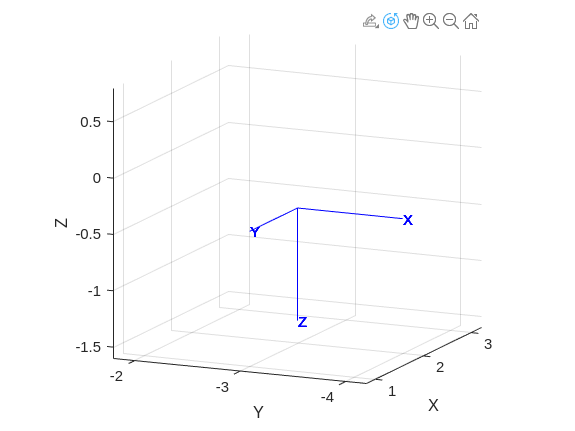

trplot(H)
hold on;


% Negative after
M = -M;
M;
[U, S, V] = svd(M(1:3, 1:2));
R = U(1:3, 1:2) * V';
R3 = cross(R(1:3, 1), R(1:3, 2));
D = det([R(1:3, 1), R(1:3, 2), R3]);
lambda = abs(trace(R' * M(1:3, 1:2))/trace(M(1:3, 1:2)'* M(1:3, 1:2)));
H = [R R3 M(1:3, 3)*lambda; 0 0 0 1];
H

H =          0   -1.0000         0    2.0000
   -1.0000         0         0   -3.0000
         0         0   -1.0000   -0.4000
         0         0         0    1.0000


%trplot(H);
%hold on;
%trplot([eye(4)])

Q = [ 2.621, 2.207, 1.707, 3.828, 2.414;
      2.646, 5.354, 3.5, 5.0, 7.0;
      5.354, 4.646, 3.5, 8.0, 8.0];

P = [ 1 3 1 4 5; 
      2 2 1 4 5; 
      3 1 1 4 2]

P =      1     3     1     4     5
     2     2     1     4     5
     3     1     1     4     2



% centroids
Q_cen = mean(Q, 2)

Q_cen =     2.5554
    4.7000
    5.9000


P_cen = mean(P, 2)

P_cen =     2.8000
    2.8000
    2.2000



% normalized
Q_norm = Q - Q_cen

Q_norm =     0.0656   -0.3484   -0.8484    1.2726   -0.1414
   -2.0540    0.6540   -1.2000    0.3000    2.3000
   -0.5460   -1.2540   -2.4000    2.1000    2.1000


P_norm = P - P_cen

P_norm =    -1.8000    0.2000   -1.8000    1.2000    2.2000
   -0.8000   -0.8000   -1.8000    1.2000    2.2000
    0.8000   -1.2000   -1.2000    1.8000   -0.2000



cross_coer = zeros(3, 3);
for i = 1:5
    cross_coer = cross_coer + Q_norm(1:3, i) * P_norm(1:3, i)';
end

[U, S, V] = svd(cross_coer);

S_prime = eye(3); S_prime(3, 3) = sign(det(V*U'));

R = U * S_prime * V'

R =     0.5001   -0.5001    0.7070
    0.8535    0.1465   -0.5000
    0.1465    0.8535    0.5001



t = Q_cen - R * P_cen

t =     1.0000
    3.0000
    1.9999



H = [R t; 0 0 0 1]

H =     0.5001   -0.5001    0.7070    1.0000
    0.8535    0.1465   -0.5000    3.0000
    0.1465    0.8535    0.5001    1.9999
         0         0         0    1.0000


P = [P; 1 1 1 1 1]

P =      1     3     1     4     5
     2     2     1     4     5
     3     1     1     4     2
     1     1     1     1     1



H*P

ans =     2.6209    2.2071    1.7070    3.8280    2.4140
    2.6464    5.3535    3.5000    5.0000    7.0001
    5.3537    4.6464    3.5000    8.0001    7.9999
    1.0000    1.0000    1.0000    1.0000    1.0000


H = [2 25 -64;
     14 -7 28;
     -0.01 0.1 1]

H =     2.0000   25.0000  -64.0000
   14.0000   -7.0000   28.0000
   -0.0100    0.1000    1.0000


p = [500; 300; 1]

p =    500
   300
     1


P = H * p

P =         8436
        4928
          26


P = P/P(3)

P =   324.4615
  189.5385
    1.0000


p = [-222; 333]

p =   -222
   333


d = 77

d = 77

f = 1234

f = 1234

B = 0.1

B = 0.1000


Z = f * B / d

Z = 1.6026

X = p(1) * B / d

X = -0.2883

Y = p(2) * B / d

Y = 0.4325

P = [0 -500 -1000 -190000; 
     1000 -500 0 -120000;
     0 -1 0 -300]

P =            0        -500       -1000     -190000
        1000        -500           0     -120000
           0          -1           0        -300


m = [767; 
     650]

m =    767
   650



M_inf = [inv(P(1:3, 1:3)) * [m; 1]]

M_inf =     0.1500
   -1.0000
   -0.2670


C = [-inv(P(1:3, 1:3)) * P(1:3, 4)]

C =    -30
  -300
   -40



% orientation should be normalized
orientation = M_inf/norm(M_inf)

orientation =     0.1434
   -0.9562
   -0.2553


moment = cross(C, orientation)

moment =    38.3423
  -13.3959
   71.7124



% back to line
point = cross(orientation, moment)

point =   -71.9889
  -20.0740
   34.7402


orientation = orientation

orientation =     0.1434
   -0.9562
   -0.2553


% 

e2 = P_2